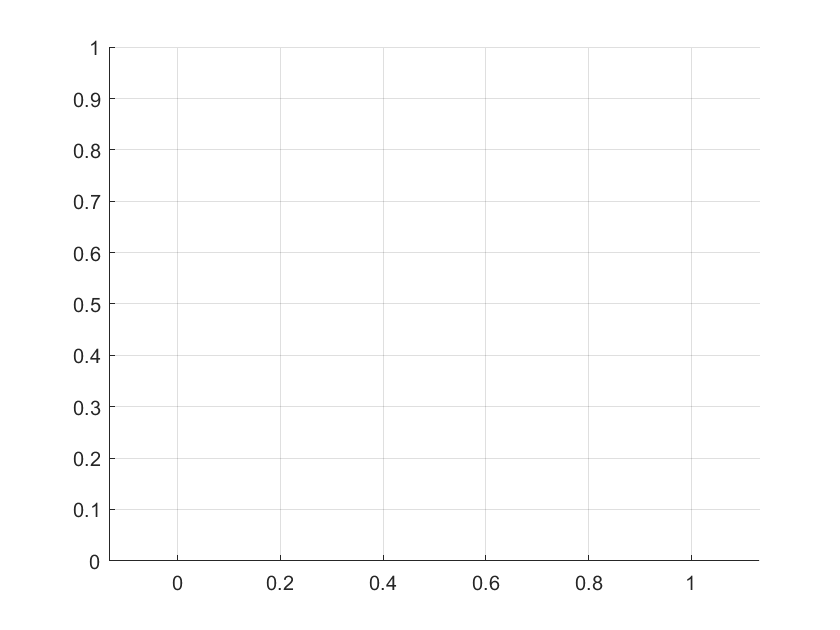

clear
close all
% environment
theta_start.coord = [0; 0];
theta_goal = [1; 1];
center = [0.5; 0.5];
radius = 0.3;
% parameters
epsilon = 0.1;
delta = 0.1;
N = 1000;
% visualize environment
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal

viscircles(center', radius, 'Color', [0.5, 0.5, 0.5]);

'viscircles' requires Image Processing Toolbox.

plot(0, 0, 'ko', 'MarkerFaceColor', 'k')
plot(1, 1, 'ko', 'MarkerFaceColor', 'k')
% initialize tree
theta_start.parent = 0;
G(1) = theta_start;
for idx = 1:N
    if nomr(G(end).coord - theta_goal) < epsilon 
        break; 
    end
    % stop if the last node in G is close to theta_goal
    %%% to implement
    % sample random joint position
    dist = zeros(length(G),1); 
    for jdx = 1:1:length(G)
        dist(jdx) = norm(G(jdx).coord-theta_rand); 
    end
    [~, theta_near_index]= min(dist)
    theta_rand = rand(2,1);
    theta_near = G(theta_near_index);
    % take a step from theta_near towards theta_rand
    vec_to_rand = theta_rand - theta_near.coord;
    dist_to_rand = norm(vec_to_rand);
    if dist_to_rand < delta
        theta_new.coord = theta_rand;
    else
        theta_new.coord = theta_near.coord + delta * ...
            vec_to_rand/dist_to_rand;
    end
    % check if theta_new is collision free
    %%% to implement
    if (theta_new.coord(1) >= 0.2 && theta_new.coord(1) <= 0.8)
        if (theta_new.coord(2) >= 0.2 && theta_new.coord(2) <= 0.8)
            % if collision free, add theta_new to tree with parent theta_near
            theta_new.parent = theta_near_index;
            G = [G, theta_new];
        end
    end
    

    
    % plot node and edge
    plot(theta_new.coord(1), theta_new.coord(2), 'o', 'Color',  [0.5, 0.5, 0.5], 'MarkerFaceColor', [0.5, 0.5, 0.5])
    line([theta_near.coord(1), theta_new.coord(1)], [theta_near.coord(2), 
theta_new.coord(2)], 'Color', 'k', 'LineWidth', 2);
    drawnow
end
% work backwards from the final node to the root of the tree
child_theta = G(end);
while child_theta.parent ~= 0
    parent_theta_index = child_theta.parent% to implement
    parent_theta =G(parent_theta_index) % to implement
    line([child_theta.coord(1), parent_theta.coord(1)], ...
        [child_theta.coord(2), parent_theta.coord(2)], ...
        'Color', [1, 0.5, 0], 'LineWidth', 3);
    child_theta = parent_theta;
end